# Лабораторная работа №7

Решение краевой задачи для  обыкновенных дифференциальных  уравнений  2-ого порядка.

ДУ:  $\textrm{𝑦}\prime \prime +4\textrm{𝑥𝑦}\prime +\left(4x^2 +3\right)\textrm{𝑦}={\textrm{𝑒}}^{-x^2 } ,\;\textrm{𝑥}\in \left\lbrack 0;1\right\rbrack$ 

Задача Коши: $\textrm{𝑦}\left(0\right)=1,\;\textrm{𝑦}\left(1\right)=\frac{1}{\textrm{𝑒}\;}$ 

Входные данные:

p = @(x) 4.*x;
q = @(x) 4.*x.^2 + 3;
f = @(x) exp(-1.*x.^2);
a = 0;
b = 1;
n = 80;
y_0 = 1;
y_n = exp(-1);

d = [a, b];

xx = linspace(d(1), d(2), n);
yy = exp(-xx.^2);

xx = linspace(d(1), d(2), n);
yy = exp(-xx.^2);
[X, Y] = kr_method(p, q, f, d, n, y_0, y_n);
figure
plot(X, Y, 'LineWidth', 1.5);
hold on;
plot(xx, yy, 'LineWidth', 1.5);
legend('Numerical', 'Explict')
disp('Error')

Error


max(abs(Y - yy))

ans = 2.9450e-05

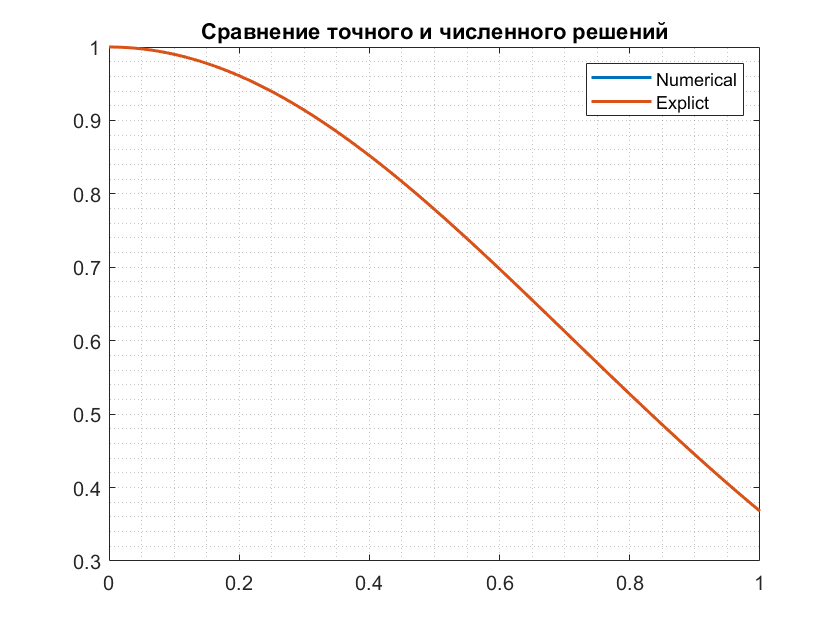

grid minor
title('Сравнение точного и численного решений')

Построени точного и численного решений:

figure
hold on
grid minor
h = [2, 3, 4, 11, 21];
lstr = [];
for i = 1:5
    [x, y] = kr_method(p, q, f, d, h(i), y_0, y_n);
    plot(x, y, 'LineWidth', 1.5);
    lstr = [lstr, "h = " + num2str(1/(h(i)-1))];
end
plot(xx, yy, 'LineWidth', 1.5);
title('Графики численного и точного решений')
lstr = [lstr, "Точное решение"]

lstr = 1×6 string array
    "h = 1"    "h = 0.5"    "h = 0.33333"    "h = 0.1"    "h = 0.05"    "Точное решение"


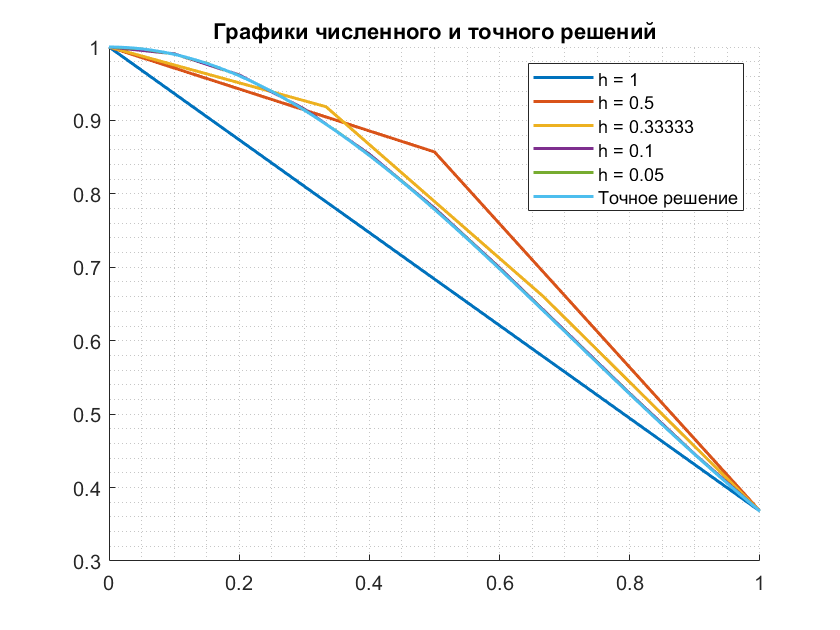

legend(lstr)

Построение зависимости погрешности метода от шага:

nmax = 100000;
 

E = [];
H = [];
n_points = 800;

points = linspace(2, nmax, n_points);

for j = 1:n_points
    disp(j);
    xx = linspace(d(1), d(2), round(points(j)));
    yy = exp(-xx.^2);
    [X, Y] = kr_method(p, q, f, d, round(points(j)), y_0, y_n);
    E(j) = max(abs(Y - yy));
    H(j) = (b-a)/round(points(j));
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



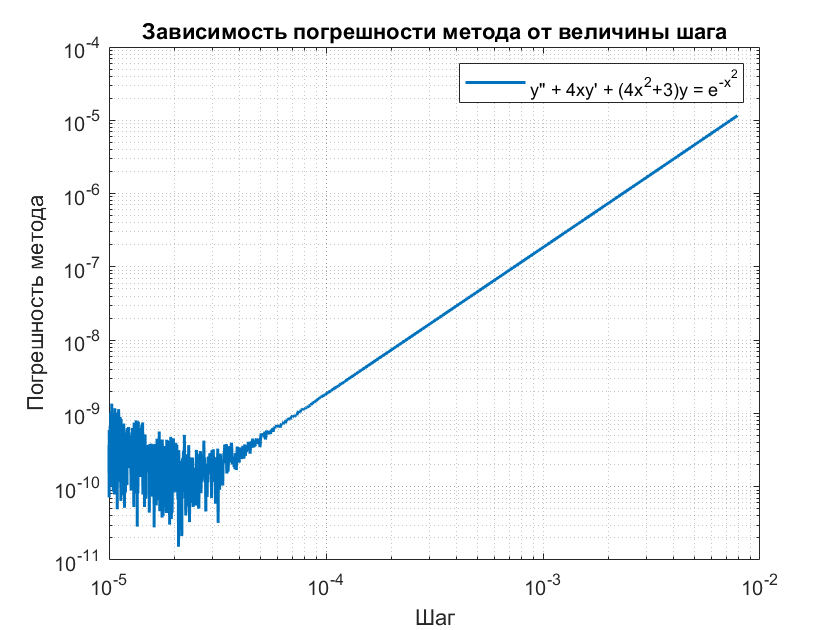


figure
loglog(H, E, 'LineWidth', 1.5);
grid minor
xlabel('Шаг')
ylabel('Погрешность метода')
title("Зависимость погрешности метода от величины шага")
legend("y'' + 4xy' + (4x^2+3)y = e^{-x^2}")

function [x, y] = kr_method(p, q, f, d, n, y_0, y_n)
    a = d(1);
    b = d(2);
    h = (b-a)/(n-1);
    x = linspace(a, b, n);
    F = @(x, y, i) (1 - h/2*p(x(i)))*y(x(i+1)) - (2 - h^2*q(x(i)))*y(x(i)) + (1 - h/2*p(x(i)))*y(x(i-1)) - h^2*f(x(i));
    D1 = zeros(1, n);
    D2 = zeros(1, n);
    D3 = zeros(1, n);
    
    for i = 2:n-1
        D1(i) = (1 - h/2*p(x(i)));
        D2(i) = -1*(2 - h^2*q(x(i)));
        D3(i) = (1 + h/2*p(x(i)));
    end
    D2(1) = 1;
    D2(n) = 1;
    B = zeros(n, 1);
    for i = 1:n
        B(i) = h^2 .* f(x(i));
    end
    B(1) = y_0;
    B(n) = y_n;
    y = (progon(D1, D2, D3, B))';
end

function x = progon(b, c, d, r)
    delta = [];
    lambda = [];
%     b = [0; b];
    delta(1) = -d(1)/c(1);
    lambda(1) = r(1)/c(1);
    n = max(size(c));
    x = zeros(n, 1);
    for i = 2:n
        if i ~= n
            delta(i) = -d(i)/(c(i) + b(i)*delta(i-1));
        end
        lambda(i) = (r(i) - b(i)*lambda(i-1))/(c(i) + b(i)*delta(i-1));
    end
    x(n) = lambda(n);
    for i = n-1:-1:1
        x(i) = delta(i)*x(i+1)+lambda(i);
    end
end